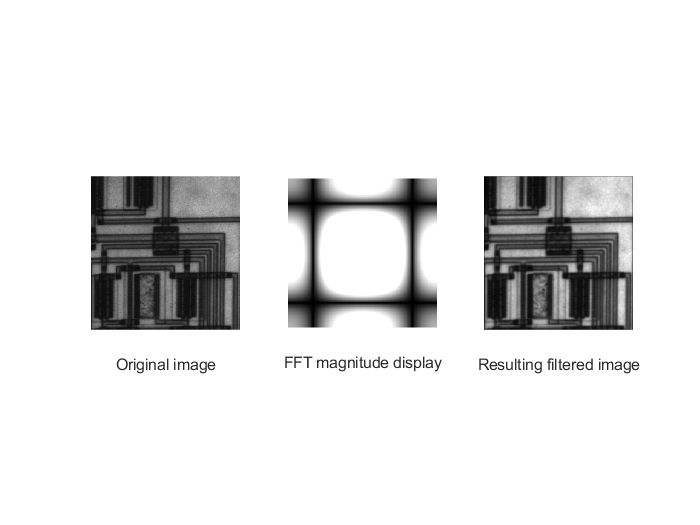

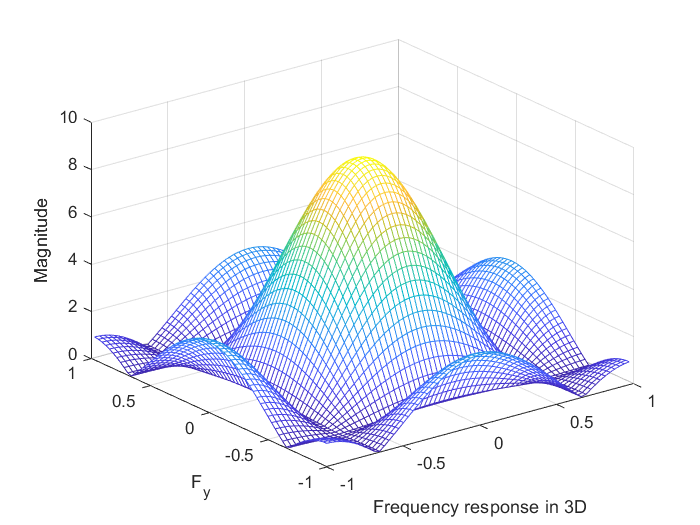

clear all;
close all;
clc;

gene_filters;
img = imread('circuit.tif');
[ima_out, H_mag, f1, f2] = Analyse_Filter(img, fmean3);

magnitude_max = max(max(H_mag));
half_power = (sqrt(2)/ 2) * magnitude_max

half_power = 6.3640

H_mag_minus_half_power = abs(H_mag - half_power)

H_mag_minu_half_power =     5.3640    5.3736    5.4024    5.4501    5.5162    5.6001    5.7010    5.8179    5.9497    6.0952    6.2528    6.4212    6.5986    6.7834    6.9738    7.1679    7.3640    7.5600    7.7541    7.9445    8.1293    8.3068    8.4751    8.6327    8.7782    8.9100    9.0269    9.1278    9.2117    9.2778    9.3255    9.3543    9.3640    9.3543    9.3255    9.2778    9.2117    9.1278    9.0269    8.9100    8.7782    8.6327    8.4751    8.3068    8.1293    7.9445    7.7541    7.5600    7.3640    7.1679
    5.3736    5.3831    5.4117    5.4589    5.5244    5.6075    5.7074    5.8232    5.9537    6.0978    6.2539    6.4206    6.5963    6.7794    6.9679    7.1602    7.3543    7.5485    7.7408    7.9293    8.1123    8.2880    8.4548    8.6109    8.7549    8.8855    9.0013    9.1012    9.1843    9.2498    9.2970    9.3255    9.3351    9.3255    9.2970    9.2498    9.1843    9.1012    9.0013    8.8855    8.7549    8.6109    8.4548    8.2880    8.1123    7.9293    7.7408    7

value = min(min(H_mag_minus_half_power));
[index, index2] = find(H_mag_minus_half_power==value)

index =     33
    23
    43
    33


index2 =     23
    33
    33
    43


f1(index)

ans =          0
   -0.3125
    0.3125
         0


f2(index2)

ans =    -0.3125
         0
         0
    0.3125
